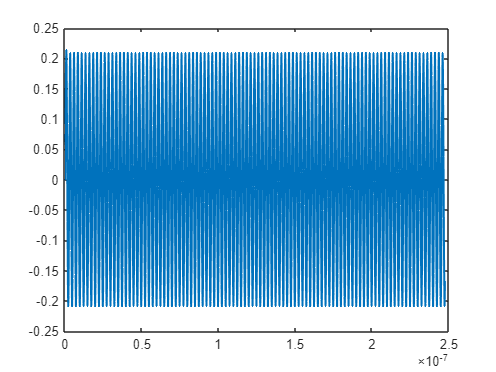

df_raw = readtable('Vout');
t = table2array(df_raw(:,1));
Vout = table2array(df_raw(:,2));
Fs = 4.096e6;

plot(t,Vout, 'LineWidth', 1.5)
hold off

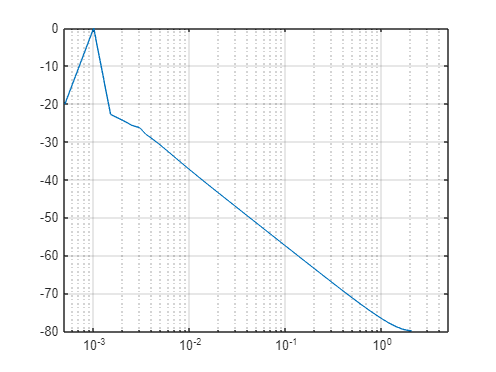


L = length(Vout);

% Forma 1
% vout_fft = fft(Vout);
% % Espectro de amplitud
% P2 = abs(vout_fft/L);         % Doble cara
% P1 = P2(1:L/2+1);      % Cara simple
% P1(2:end-1) = 2*P1(2:end-1);  % Corrige la amplitud
% 
% % Vector de frecuencias
% f = Fs*(0:(L/2))/L;
% 
% % Gráfica
% figure;
% plot(f, P1)
% title('Espectro de amplitud de x(t)')
% xlabel('Frecuencia (Hz)')
% ylabel('|X(f)|')
% grid on;
% xlim([0,5000])

% Forma 2 + Normalizacion
NFFT_PLOT = 1024*8;
vec_frec = (0:NFFT_PLOT-1)* Fs / NFFT_PLOT; 

H_vout = 20*log10(abs(fft(Vout, NFFT_PLOT))/max(abs(fft(Vout, NFFT_PLOT))));

pos = 1:(floor(NFFT_PLOT/2)+1);
vec_frec_pos = vec_frec(pos);
H_vout_db = H_vout(pos);

figure;
semilogx(vec_frec_pos/1e6, H_vout_db);
xlim([0,5]);
grid on;


figure;
stem(P1)

Unrecognized function or variable 'P1'.


% Parámetros de la señal
Fs = 1000;             % Frecuencia de muestreo (Hz)
T = 1/Fs;              % Periodo de muestreo
L = 1000;              % Longitud de la señal
t = (0:L-1)*T;         % Vector de tiempo

% Señal senoidal
f0 = 50;               % Frecuencia de la señal (Hz)
x = sin(2*pi*f0*t);    % Señal senoidal

% FFT
Y = fft(x);

% Espectro de amplitud
P2 = abs(Y/L);         % Doble cara
P1 = P2(1:L/2+1);      % Cara simple
P1(2:end-1) = 2*P1(2:end-1);  % Corrige la amplitud

% Vector de frecuencias
f = Fs*(0:(L/2))/L;

% Gráfica
figure;
plot(f, P1)
title('Espectro de amplitud de x(t)')
xlabel('Frecuencia (Hz)')
ylabel('|X(f)|')
grid on;
xlim([40,60])